# Laboratorium X

# Filtry FIR, filtracja sygnałów

## Wstęp teoretyczny:

    Filtracja jest procesem przetwarzania sygnału w dziedzinie czasu. Polega na redukowaniu (odfiltrowaniu) niepożądanych składowych zawartych w sygnale wejściowym. Filtracja to usuwanie szumu z sygnału/obrazu. Intuicyjnie szum jest stochastycznym odchyleniem sygnału od jego wartości rzeczywistej. Zadaniem filtracji jest eliminacja tego szumu głównie za pomocą metod przetwarzania sygnału/obrazu. W procesie przetwarzania filtry wykorzystywane są między innymi do: 

-  poprawy złej jakości technicznej sygnału, 

-  korekcji określonych wad sygnału, 

-  wzmocnienia w sygnale pewnych elementów zgodnych z posiadanym wzorcem, 

-  stłumienia w sygnale niepożądanego szumu, 

-  rekonstrukcji poszczególnych fragmentów sygnału, które uległy częściowemu uszkodzeniu.  

Ze względu na typ przetwarzanych sygnałów filtrację dzieli się na: 

**-Analogową **(filtr analogowy działa na sygnale ciągłym, filtr = układ elektroniczny, np. RLC ) 

**-Cyfrową** (przetwarzanie ciągu wartości próbek, filtr = program komputerowy)

Ze względu na sposób przetwarzania sygnału, filtry cyfrowe dzieli się na: 

**-Filtry FIR **(Nierekursywne, o skończonej odpowiedzi impulsowej SOI, ang. Finite Impulse Response - FIR) **-Filtry IIR** (Rekursywne, o nieskończonej odpowiedzi impulsowej NOI, ang. Infinite Impulse Response - IIR) 

Charakterystyki widmowe filtrów cyfrowych: 

**Transmitancję filtru cyfrowego definiuje się jako stosunek transformaty zet sygnału wyjściowego do transformaty zet sygnału wejściowego. **

Transmitancja operatorowa (funkcja przejścia, G(s)) – stosunek transformaty Laplace'a sygnału wyjściowego do transformaty Laplace'a sygnału wejściowego układu przy zerowych warunkach początkowych.

####     Na czym polega proces filtracji?

    Filtracja jest to proces przetwarzania dokonywany na sygnale w dziedzinie czasu. Proces ten powoduje zmiany w widmie sygnału oryginalnego. Zmiana polega na odfiltrowaniu pewnych niepożądanych składowych sygnału wejściowego. Można zatem powiedzieć, że filtr przepuszcza pewne częstotliwości a inne tłumi. Sygnał ciągły jest filtrowany przez filtr analogowy. Natomiast sygnał cyfrowy jest filtrowany przez filtr cyfrowy.Filtr cyfrowy może być na przykład układem scalonym, programowalnym procesorem lub programem komputerowym. Tradycyjne liniowe filtry cyfrowe występują jako jeden z dwóch typów: filtry o skończonej odpowiedzi impulsowej SOI (ang. Finite Impulse Response - FIR) i filtry o nieskończonej odpowiedzi impulsowej NOI (ang. Infinite Impulse Response - IIR).

####     Filtry o skończonej odpowiedzi impulsowej (FIR)

    Zasadniczą cechą charakteryzującą ten rodzaj filtrów jest to, że do uzyskania bieżącej próbki sygnału na wyjściu filtru wykorzystują one próbkę bieżącą i próbki przeszłe sygnału wejściowego, nie korzystając z żadnych przeszłych próbek sygnału wyjściowego. Z tego powodu nazywa się je czasem filtrami nierekursywnymi. Nazwa ich wzięła się stąd, że filtry te, dysponując skończoną liczbą różnych od zera próbek sygnału wejściowego, na wyjściu zawsze mają skończoną liczbę próbek sygnału wyjściowego. Może inaczej. Jeśli na wejściu filtru FIR pojawi się nagle ciąg próbek o zerowej wartości, na wyjściu również otrzymamy ciąg, którego wartości będą równe zero. Może to wydaje się oczywiste, ale, jak się przekonamy później, wcale takie nie musi być (filtry IIR). Jednakże w przypadku KAŻDEGO filtru typu FIR powyższy warunek jest ZAWSZE spełniony.

####     Okna

    Co prawda nie pozbędziemy się zafalowań całkowicie, jak i nigdy nie osiągniemy filtrów o zboczach idealnie pionowych, ale możemy je minimalizować. Pamiętcie może, jak poradziliśmy sobie ze stratą zafalowań w DFT? Oczywiście okna. Widzimy więc, że cyfrowe przetwarzanie sygnałów rządzi się pewnymi żelaznymi prawami, które obowiązują wszędzie: w DFT, w FFT i także w filtracji cyfrowej. Są to dwie generalne zasady: 

- zwiększając ilość próbek (współczynników) polepszamy rozdzielczość (stromość zboczy) 

- stosując okna zmniejszamy zafalowania charakterystyki kosztem rozdzielczości (zmniejszenie nachylenia)

####     Faza filtrów FIR

    Na zakończenie tematu o filtrach FIR kilka zdań o fazie, gdyż, jak się okazuje, jest to bardzo ważna właściwość tych filtrów. A mianowicie filtry FIR, mające symetryczne współczynniki, oferują liniową charakterystykę fazy w paśmie przenoszenia, dzięki czemu to właśnie te filtry są chętniej wybierane, niż filtry IIR. Czytelnik mógłby się dziwić, cóż tak istotnego jest w tym fakcie. Ano jest, gdyż ma to wpływ na tzw. opóźnienia grupowe. Opóźnienie grupowe w filtrach FIR jest stałe (gdyż faza jest liniowa), co oznacza, że wszystkie składowe częstotliwościowe sygnału wejściowego są jednakowo opóźniane, a to z kolei oznacza, że nie ma żadnych zniekształceń fazowych w sygnale wyjściowym. Ma to kapitalne znaczenie, gdyż w przypadku sygnałów cyfrowych zniekształcenia fazowe są o wiele bardziej "nieprzyjemne", niż zniekształcenia amplitudowe, a więc jest to bardzo istotna zaleta filtrów FIR.

## Przebieg ćwiczenia

    Po zapoznaniu się ze wstepem teoretycznym oraz przykładami zamieszczonymi w konspekcie, przeszedłem do wykonywania poszczegołnych zadań.

**Zadanie 1.**

Korzystając z Przykładu 2 zaprojektować filtr wycinający składowe częstotliwości od 50-70 Hz. 

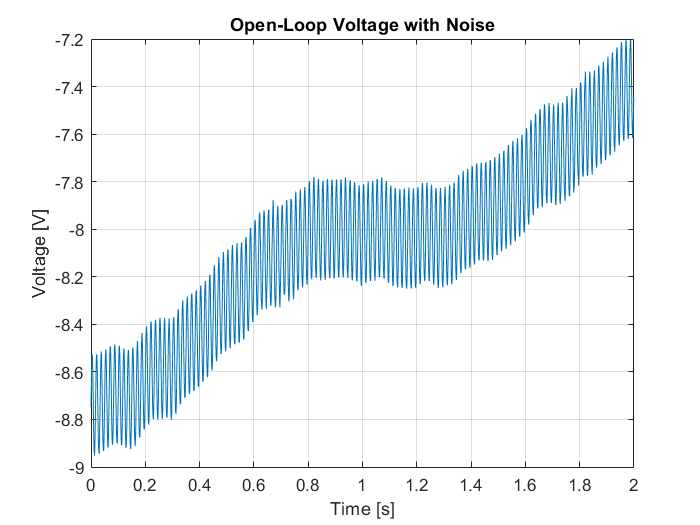

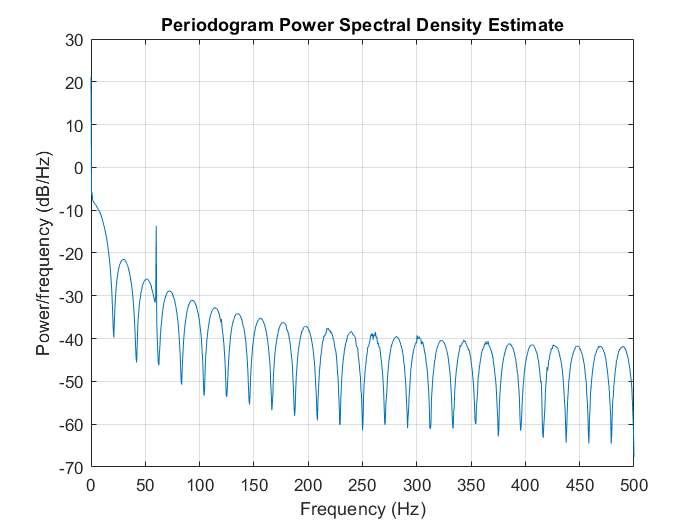

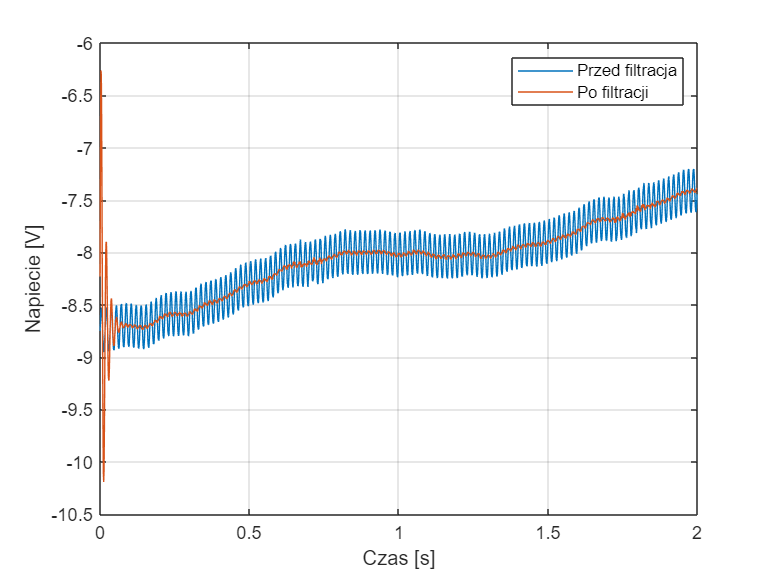

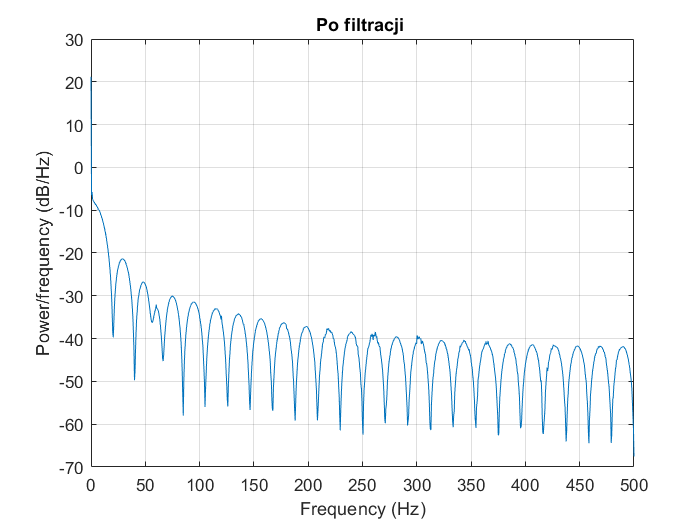

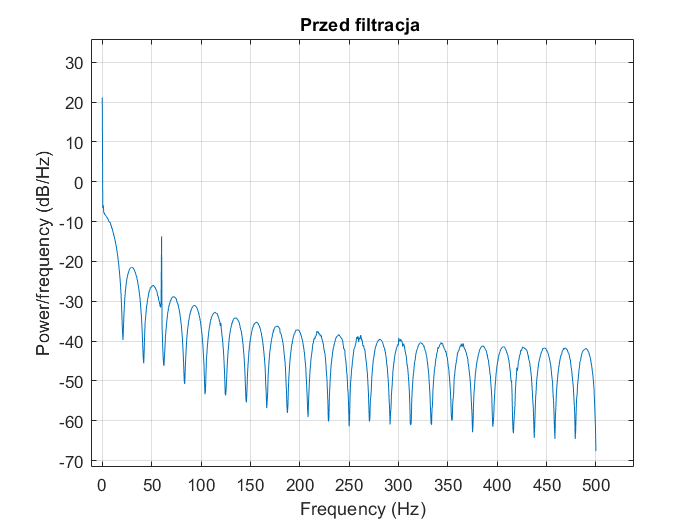

zad1(50, 70)

Widzimy, że zaprojektowany przeze mnie filtr zdał egzamin i bardzo dobrze usunął zakłocenie występujące dla częstotliwości 60 Hz co możemy zauważyć na dwóch ostatnich wykresach.

**Zadanie 2.**

Zaprojektować filtr o transmitancji:

dla ciągu: 

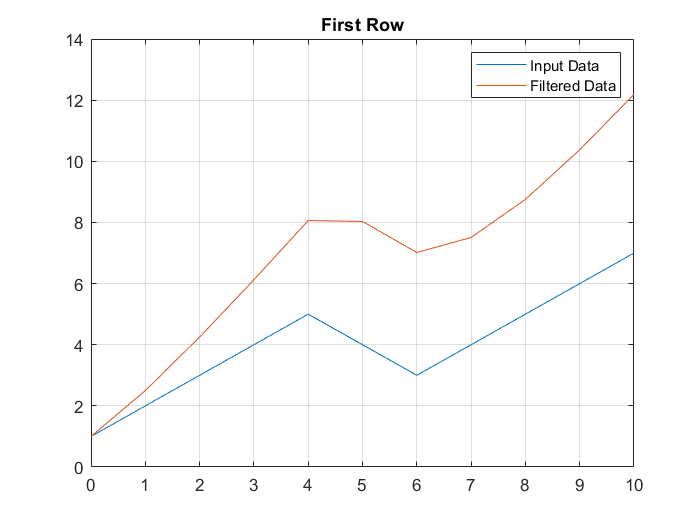

clear all;
x = [1, 2, 3, 4, 5, 4, 3, 4, 5, 6, 7];
b = 1;
a = [1 -0.5];
y = filter(b,a,x,[],2);
t = 0:length(x)-1; %indeks wektora
plot(t,x(1,:))
hold on
plot(t,y(1,:))
legend('Input Data','Filtered Data');grid on;
title('First Row')
hold off

**Zadanie 3.**

Zaprojektować filtr o transmitancji:

dla ciągu: 

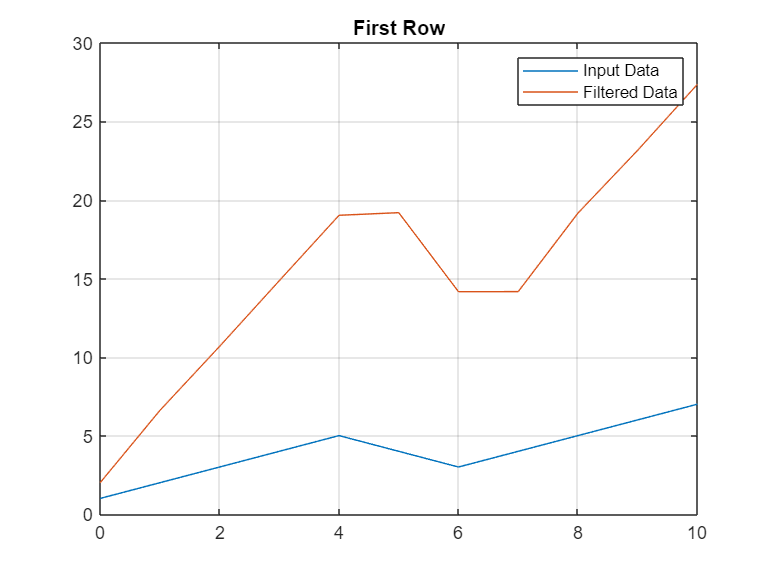

clear all;
x = [1, 2, 3, 4, 5, 4, 3, 4, 5, 6, 7];
b = [2 3];
a = [1 0.2];
y = filter(b,a,x,[],2);
t = 0:length(x)-1; %indeks wektora
plot(t,x(1,:))
hold on
plot(t,y(1,:))
legend('Input Data','Filtered Data');grid on;
title('First Row')
hold off

**Zadanie 4.**

Na podstawie przykładu 4 zaprojektować filtr dolnoprzepustowy. Wczytać sygnał chirp. Filtr odcina wysokie częstotliwości w 0,48. Pozostałe parametry jak okno Czebyszewa ustawić na 30 dB i sprawdzić jego działanie. 

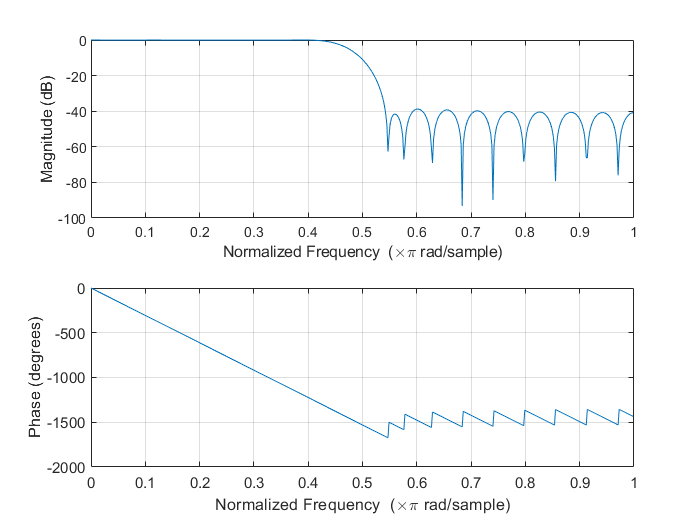

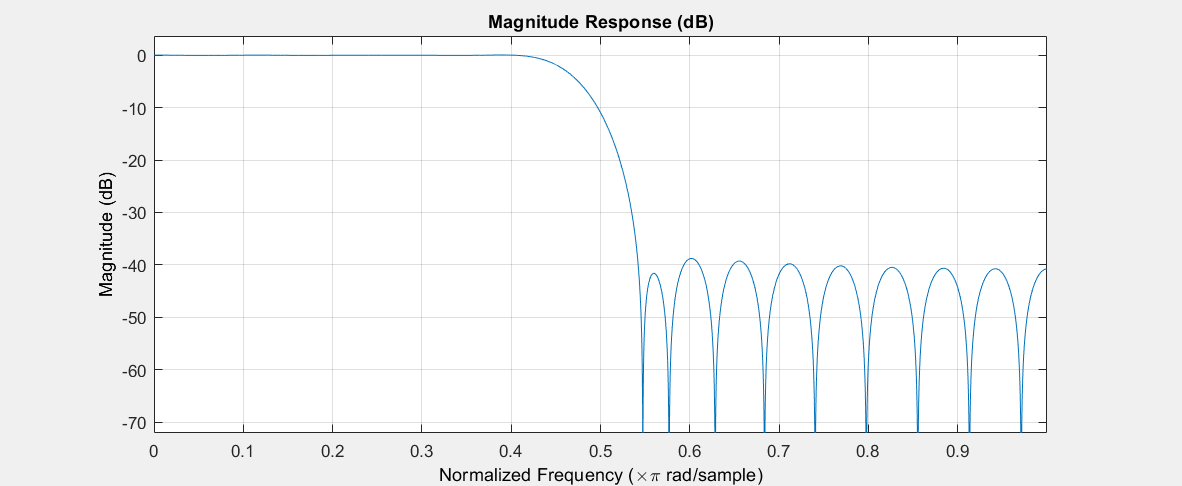

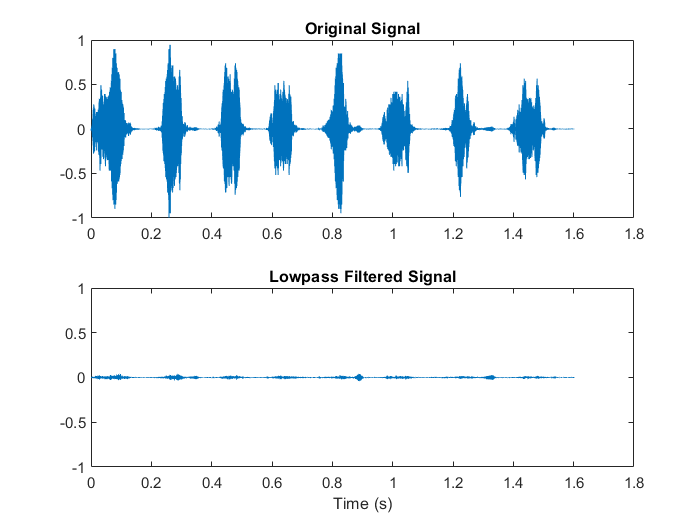

zad4('low')

**Zadanie 5.**

Na podstawie przykładu 5 zaprojektować filtr, który będzie przepuszczać częstotliwości tłumione. Natomiast tłumić będzie te przepuszczane.

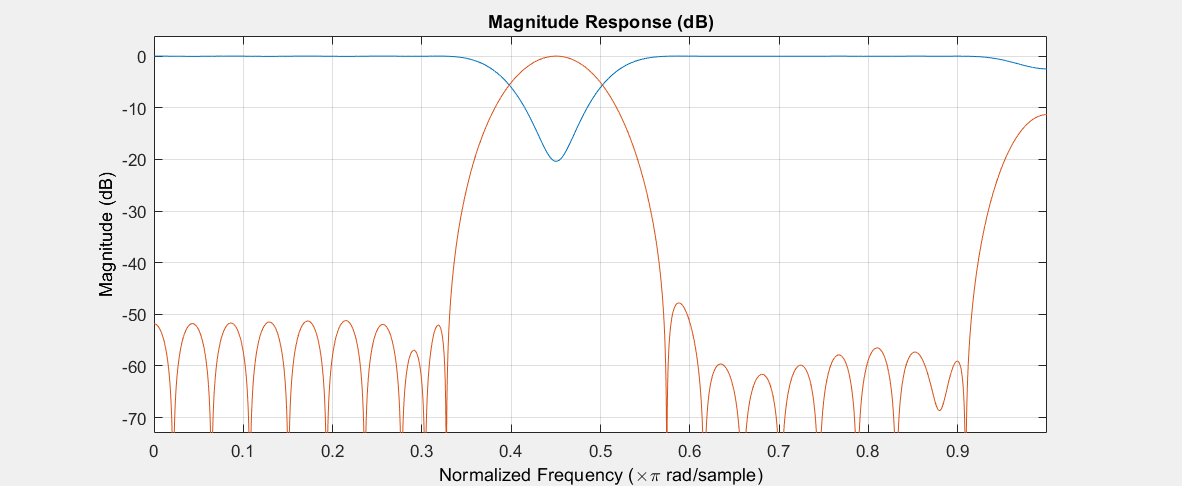

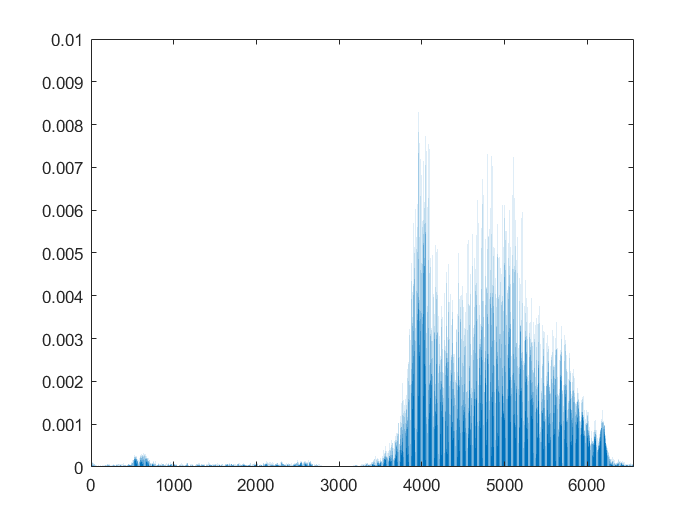

zad5()

**Zadanie 6.**

Zad 6 Na podstawie przykładu 6 zaprojektować filtr, który używa okna Tukey ('Tukey'). Porównać filtry z oknem Hamminga ('Hamming') i Tukey

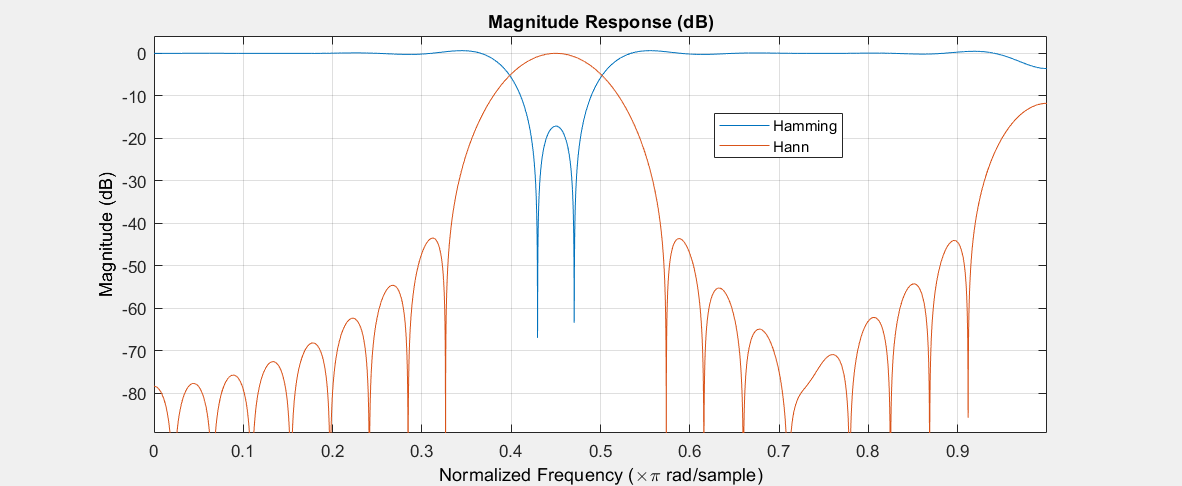

zad6()

**Zadanie 7.**

Korzystając z Przykładu 8, wyciąć składowe częstotliwości 500-1000 i przeprowadzić rozpoznawanie. Zaobserwować wyniki.

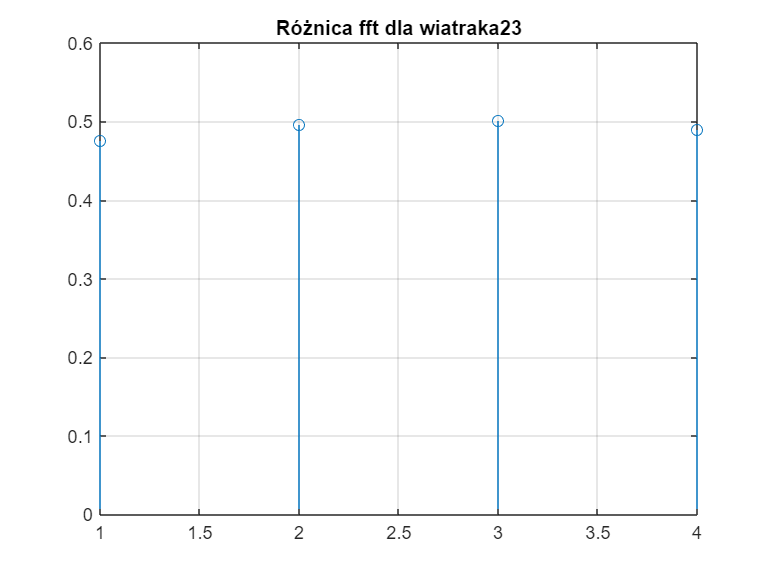

wiatrak20 = importdata("wiatrak_20.wav");
wiatrak21 = importdata("wiatrak_21.wav");
wiatrak23 = importdata("wiatrak_23.wav");
wiatrak24 = importdata("wiatrak_24.wav");
przekladnia20 = importdata("przekladnia20.wav");
przekladnia21 = importdata("przekladnia21.wav");
przekladnia23 = importdata("przekladnia23.wav");
przekladnia24 = importdata("przekladnia24.wav");

%dla wiatraka 20
data = wiatrak20.data;
max_data=max(abs(data));
data=data/max_data;
xfftw20=abs(fft(wiatrak20.data));
xfftw20=xfftw20/44100; 
xfftw20(1:501) = 0;
xfftw20(1001:44100) = 0;

% normalizacja do przedzialu [-1, 1] jesli sygnaly sa mierzone w roznych odleglosciach

%dla wiatraka 21


data = wiatrak21.data;
max_data1=max(abs(data));
data=wiatrak20.data/max_data1;
xfftw21=abs(fft(wiatrak21.data));
xfftw21=xfftw21/44100; 
xfftw21(1:501) = 0;
xfftw21(1001:44100) = 0;

%dla wiatraka 23
clear data; clear max_data1;

data = wiatrak23.data;
max_data1=max(abs(data));
data=data/max_data1;
xfftw23=abs(fft(wiatrak23.data));
xfftw23=xfftw23/44100; 
xfftw23(1:501) = 0;
xfftw23(1001:44100) = 0;

%dla wiatraka 24
clear data; clear max_data1;

data = wiatrak24.data;
max_data1=max(abs(data));
data=data/max_data1;
xfftw24=abs(fft(wiatrak24.data));
xfftw24=xfftw24/44100; 
xfftw24(1:501) = 0;
xfftw24(1001:44100) = 0;

%dla przekładni 20
clear data; clear max_data1;

data = przekladnia20.data;
max_data1=max(abs(data));
data=data/max_data1;
xfftp20=abs(fft(przekladnia20.data));
xfftp20=xfftp20/44100; 
xfftp20(1:501) = 0;
xfftp20(1001:44100) = 0;

%dla przekładni 21
clear data; clear max_data1;

data = przekladnia21.data;
max_data1=max(abs(data));
data=data/max_data1;
xfftp21=abs(fft(przekladnia21.data));
xfftp21=xfftp21/44100; 
xfftp21(1:501) = 0;
xfftp21(1001:44100) = 0;

%dla przekładni 23
clear data; clear max_data1;

data = przekladnia23.data;
max_data1=max(abs(data));
data=data/max_data1;
xfftp23=abs(fft(przekladnia23.data));
xfftp23=xfftp23/44100; 
xfftp23(1:501) = 0;
xfftp23(1001:44100) = 0;

%dla przekładni 24
clear data; clear max_data1;

data = przekladnia24.data;
max_data1=max(abs(data));
data=data/max_data1;
xfftp24=abs(fft(przekladnia24.data));
xfftp24=xfftp24/44100; 
xfftp24(1:501) = 0;
xfftp24(1001:44100) = 0;


D_w23= [];
D_w23(1)= sum(abs(xfftw23-xfftw20));
D_w23(2)= sum(abs(xfftw23-xfftw21));
D_w23(3)= sum(abs(xfftw23-xfftp20));
D_w23(4)= sum(abs(xfftw23-xfftp21));

D_w24= [];
D_w24(1)=sum(abs(xfftw24-xfftw20));
D_w24(2)=sum(abs(xfftw24-xfftw21));
D_w24(3)=sum(abs(xfftw24-xfftp20));
D_w24(4)=sum(abs(xfftw24-xfftp21));

D_p23= [];
D_p23(1)= sum(abs(xfftp23-xfftw20));
D_p23(2)= sum(abs(xfftp23-xfftw21));
D_p23(3)= sum(abs(xfftp23-xfftp20));
D_p23(4)= sum(abs(xfftp23-xfftp21));

D_p24= [];
D_p24(1)= sum(abs(xfftp24-xfftw20));
D_p24(2)= sum(abs(xfftp24-xfftw21));
D_p24(3)= sum(abs(xfftp24-xfftp20));
D_p24(4)= sum(abs(xfftp24-xfftp21));

stem(D_w23); grid on; title("Różnica fft dla wiatraka23");

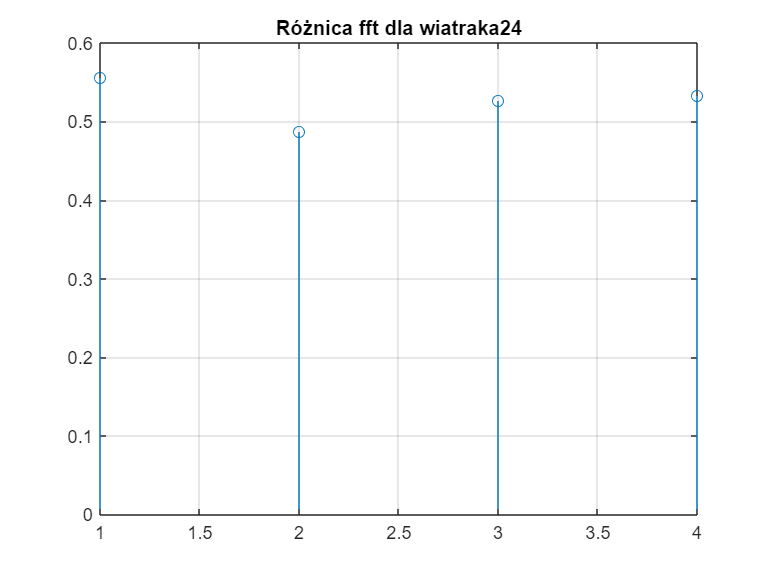

stem(D_w24); grid on; title("Różnica fft dla wiatraka24");

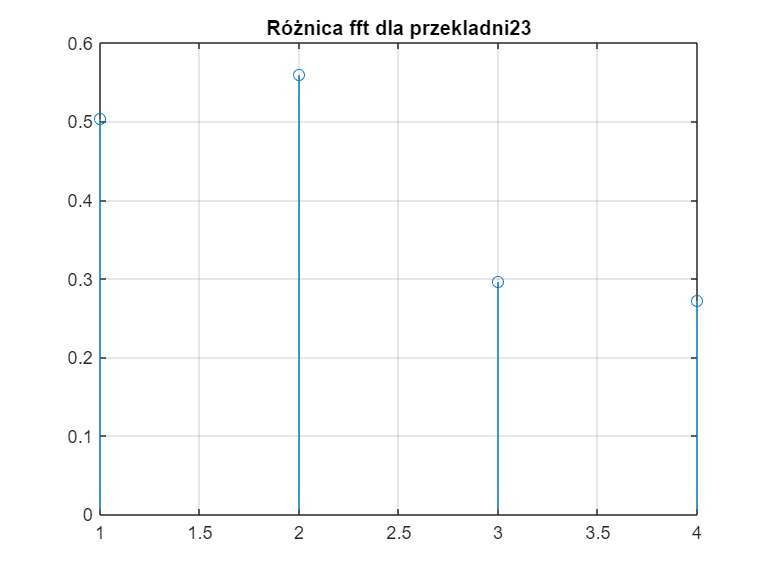

stem(D_p23); grid on; title("Różnica fft dla przekladni23");

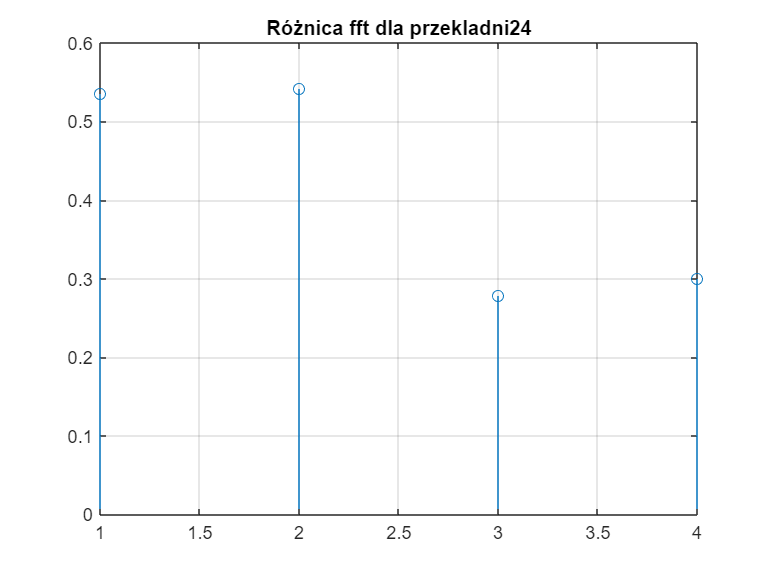

stem(D_p24); grid on; title("Różnica fft dla przekladni24");

**Zadanie 8.**

Korzystając z Przykładu 8, wyciąć składowe częstotliwości 100-1500 i przeprowadzić rozpoznawanie. Zaobserwować wyniki. 

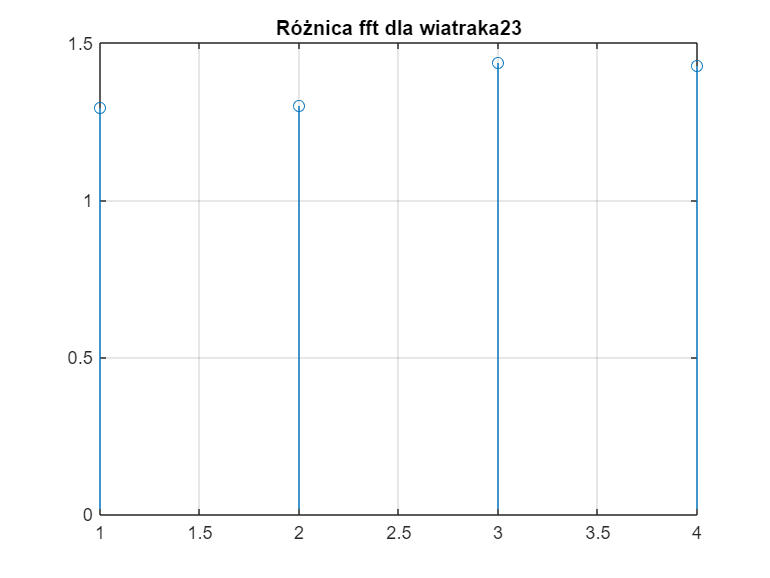

%dla wiatraka 20
data = wiatrak20.data;
max_data=max(abs(data));
data=data/max_data;
xfftw20=abs(fft(wiatrak20.data));
xfftw20=xfftw20/44100; 
xfftw20(1:101) = 0;
xfftw20(1501:44100) = 0;

% normalizacja do przedzialu [-1, 1] jesli sygnaly sa mierzone w roznych odleglosciach

%dla wiatraka 21


data = wiatrak21.data;
max_data1=max(abs(data));
data=wiatrak20.data/max_data1;
xfftw21=abs(fft(wiatrak21.data));
xfftw21=xfftw21/44100; 
xfftw21(1:101) = 0;
xfftw21(1501:44100) = 0;

%dla wiatraka 23
clear data; clear max_data1;

data = wiatrak23.data;
max_data1=max(abs(data));
data=data/max_data1;
xfftw23=abs(fft(wiatrak23.data));
xfftw23=xfftw23/44100; 
xfftw23(1:101) = 0;
xfftw23(1501:44100) = 0;

%dla wiatraka 24
clear data; clear max_data1;

data = wiatrak24.data;
max_data1=max(abs(data));
data=data/max_data1;
xfftw24=abs(fft(wiatrak24.data));
xfftw24=xfftw24/44100; 
xfftw24(1:101) = 0;
xfftw24(1501:44100) = 0;

%dla przekładni 20
clear data; clear max_data1;

data = przekladnia20.data;
max_data1=max(abs(data));
data=data/max_data1;
xfftp20=abs(fft(przekladnia20.data));
xfftp20=xfftp20/44100; 
xfftp20(1:101) = 0;
xfftp20(1501:44100) = 0;

%dla przekładni 21
clear data; clear max_data1;

data = przekladnia21.data;
max_data1=max(abs(data));
data=data/max_data1;
xfftp21=abs(fft(przekladnia21.data));
xfftp21=xfftp21/44100; 
xfftp21(1:101) = 0;
xfftp21(1501:44100) = 0;

%dla przekładni 23
clear data; clear max_data1;

data = przekladnia23.data;
max_data1=max(abs(data));
data=data/max_data1;
xfftp23=abs(fft(przekladnia23.data));
xfftp23=xfftp23/44100; 
xfftp23(1:101) = 0;
xfftp23(1501:44100) = 0;

%dla przekładni 24
clear data; clear max_data1;

data = przekladnia24.data;
max_data1=max(abs(data));
data=data/max_data1;
xfftp24=abs(fft(przekladnia24.data));
xfftp24=xfftp24/44100; 
xfftp24(1:101) = 0;
xfftp24(1501:44100) = 0;


D_w23= [];
D_w23(1)= sum(abs(xfftw23-xfftw20));
D_w23(2)= sum(abs(xfftw23-xfftw21));
D_w23(3)= sum(abs(xfftw23-xfftp20));
D_w23(4)= sum(abs(xfftw23-xfftp21));

D_w24= [];
D_w24(1)=sum(abs(xfftw24-xfftw20));
D_w24(2)=sum(abs(xfftw24-xfftw21));
D_w24(3)=sum(abs(xfftw24-xfftp20));
D_w24(4)=sum(abs(xfftw24-xfftp21));

D_p23= [];
D_p23(1)= sum(abs(xfftp23-xfftw20));
D_p23(2)= sum(abs(xfftp23-xfftw21));
D_p23(3)= sum(abs(xfftp23-xfftp20));
D_p23(4)= sum(abs(xfftp23-xfftp21));

D_p24= [];
D_p24(1)= sum(abs(xfftp24-xfftw20));
D_p24(2)= sum(abs(xfftp24-xfftw21));
D_p24(3)= sum(abs(xfftp24-xfftp20));
D_p24(4)= sum(abs(xfftp24-xfftp21));

stem(D_w23); grid on; title("Różnica fft dla wiatraka23");

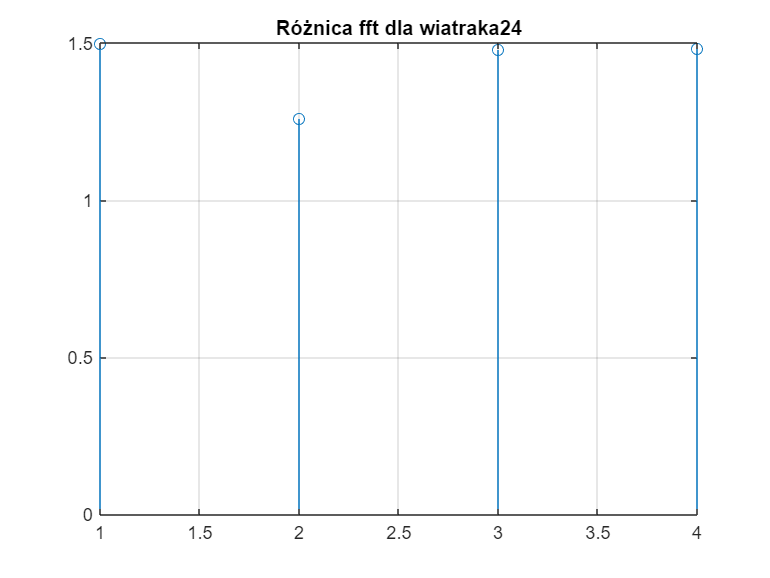

stem(D_w24); grid on; title("Różnica fft dla wiatraka24");

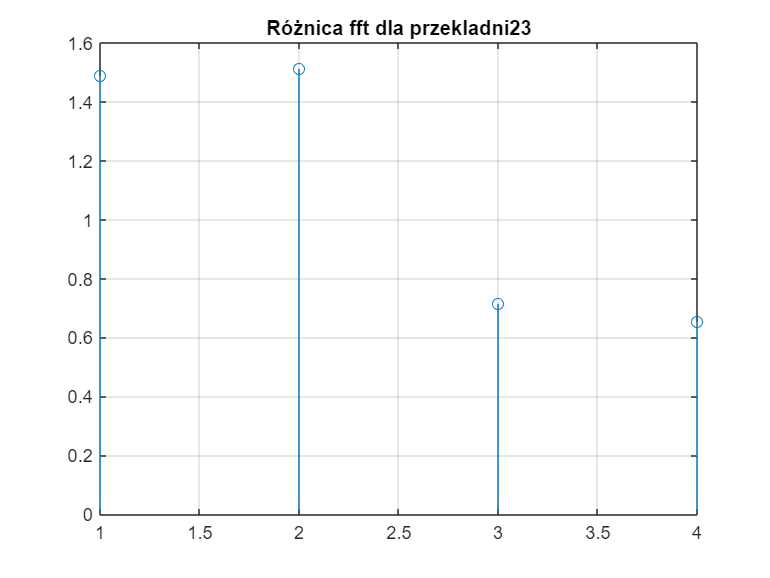

stem(D_p23); grid on; title("Różnica fft dla przekladni23");

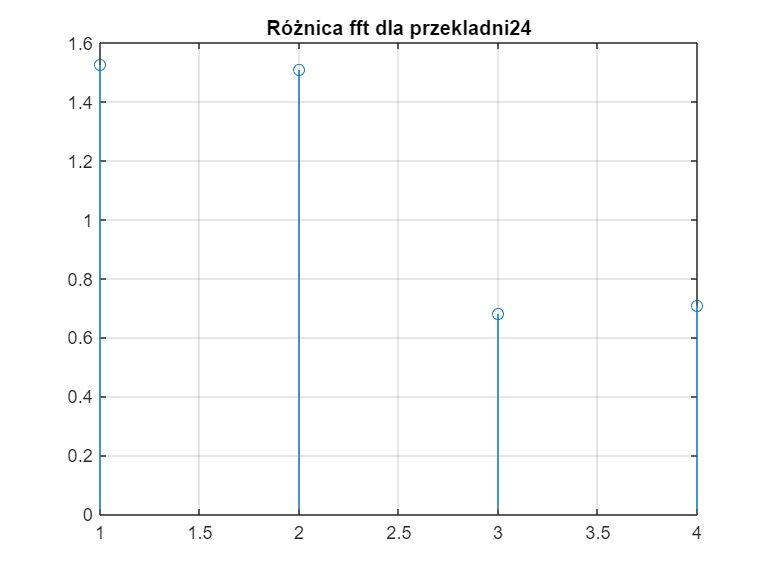

stem(D_p24); grid on; title("Różnica fft dla przekladni24");